# OUTPUTS

This script allows the user to view standard outputs from the Half Car model and also define custom output channels

** THIS SCRIPT IS USED TO DISPLAY OUTPUTS OF "`HalfCarModel_11_Aero.m`"

** NOTE 

This script is divided into many different sections. The grouping is done based on some similarities. 

To run the sections individually (which will save time) click anywhere on the section and then click the 

`Run Section` button.

A section is demarcated by a blue border.

## Extracting All Basic Outputs

% Sprung Mass Deflection
o.zs = y(:,1); 
% Sprung Mass Pitch 
o.phi = y(:,2);
% Unsprung Mass 1 Deflection
o.za1 = y(:,3);
% Unsprung Mass 2 Deflection
o.za2 = y(:,4);
% Sprung Mass Deflection
o.zs_d = y(:,5); 
% Sprung Mass Pitch 
o.phi_d = y(:,6);
% Unsprung Mass 1 Deflection
o.za1_d = y(:,7);
% Unsprung Mass 2 Deflection
o.za2_d = y(:,8);
% Front Wheel Angular Velocity
o.omega1 = y(:,10);
% Front Wheel Slip Ratio
o.sr1 = y(:,11);
% Front Wheel Angular Velocity
o.omega2 = y(:,13);
% Front Wheel Slip Ratio
o.sr2 = y(:,14);
% Vehicle Longitudinal Position 
o.x = y(:,15);
% Vehicle Longitudinal Velocity
o.Vx = y(:,16);
% Initializing Time Vector
time = t;

## Road Input Profile

Creating a Road Input Profile for the uer to view

% Creating the Road Profile used as input
zr1 = interp1(hcar.simInputs3.time,hcar.simInputs3.zr1, ...
    t,'linear',"extrap");
zr2 = interp1(hcar.simInputs3.time,hcar.simInputs3.zr2, ...
    t,'linear',"extrap");

% Creating Velocity of the Road Profile used as input
zr1_d = interp1(hcar.simInputs3.time,hcar.simInputs3.zr1_d, ...
    t,'linear',"extrap");
zr2_d = interp1(hcar.simInputs3.time,hcar.simInputs3.zr2_d, ...
    t,'linear',"extrap");

## Acceleration Input

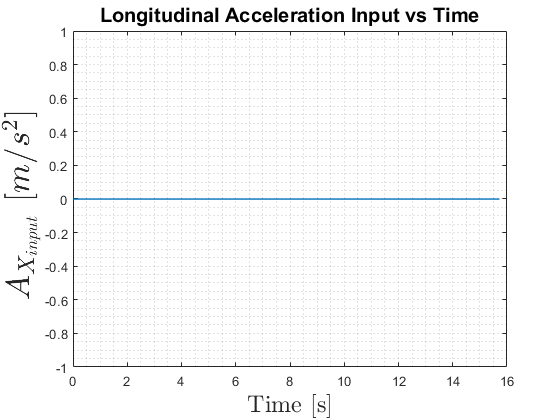

% Creating Acceleration Profile
ax_In = interp1(hcar.simInputs3.time,hcar.simInputs3.acc, ...
    t,'linear',"extrap");

% Display
plot(time,ax_In,'LineWidth',1);
title("Longitudinal Acceleration Input vs Time",'FontSize',15);
ylabel({'$A_{X_{input}}\ [m/s^2]$ '},'Interpreter','latex','FontSize',25);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

## Force Input

% Creating the Force Profiles
Fx_In = (hcar.mass_sm+hcar.mass_usm_1+hcar.mass_usm_2).*ax_In;

% Front Force 
Fx_In_1 = hcar.simInputs3.forceDis.*Fx_In;

% Rear Force
Fx_In_2 = Fx_In - Fx_In_1;

## Moment Input Profile

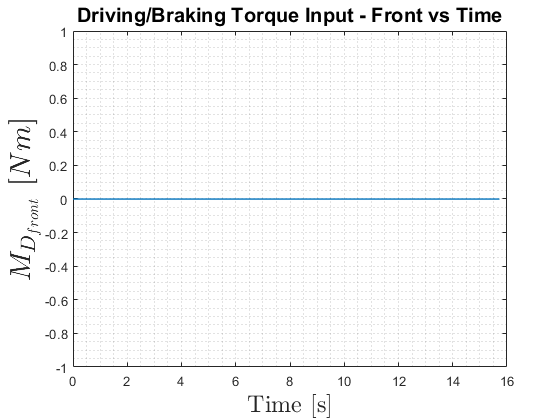

% Creating Moment Input Profile
Md_1 = Fx_In_1.*(hcar.tire1.unloadedRadius - (zr1 - y(3)))*hcar.simInputs3.GainMD_1;
Md_2 = Fx_In_2.*(hcar.tire2.unloadedRadius - (zr2 - y(4)))*hcar.simInputs3.GainMD_2;

% Display
plot(time,Md_1,'LineWidth',1);
title("Driving/Braking Torque Input - Front vs Time",'FontSize',15);
ylabel({'$M_{D_{front}}\ [Nm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

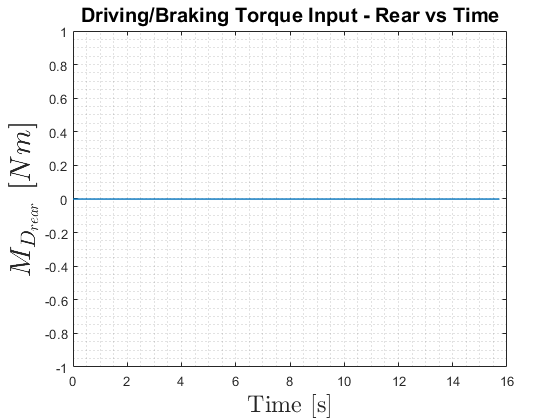


plot(time,Md_2,'LineWidth',1);
title("Driving/Braking Torque Input - Rear vs Time",'FontSize',15);
ylabel({'$M_{D_{rear}}\ [Nm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Aerodynamic Downforce Profile

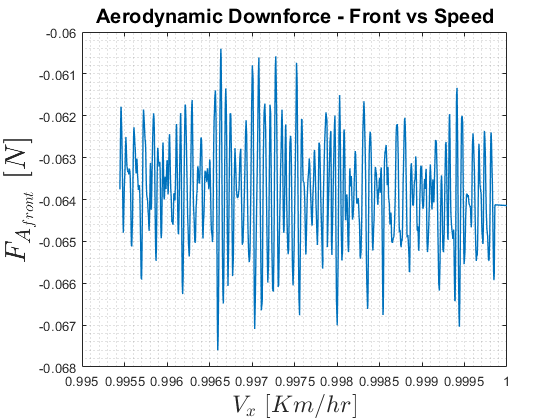

% Creating the Aero Downforce Profile

% --------------------- RIDE HEIGHTS ------------------------ %
frh = hcar.rh_1 - ((y(:,3) - r.init(3)) - (y(:,1) - r.init(1)) + hcar.dis_a12cg*(y(:,2) - r.init(2)));
rrh = hcar.rh_2 - ((y(:,4) - r.init(4)) - (y(:,1) - r.init(1)) - hcar.dis_a22cg*(y(:,2) - r.init(2)));

% --------------------- AERO PROPERTIES ------------------------ %
[cDown,cDrag,aeroBalance] = hcar.aero.Get_Aero(frh,rrh);

% --------------------- AERO DOWN FORCE------------------------ %
Faero_down = -0.5*hcar.aero.airDensity*hcar.aero.fArea.*cDown.*o.Vx.^2;
Faero_down_1 = (aeroBalance/100).*Faero_down;
Faero_down_2 = (1 - aeroBalance/100).*Faero_down;

% --------------------- AERO DRAG FORCE------------------------ %
Faero_drag = 0.5*hcar.aero.airDensity*hcar.aero.fArea.*cDrag.*o.Vx.^2;

% --------------------- AERO DRAG POWER------------------------ %
Paero_drag = Faero_drag.*o.Vx;

vel_kmph = o.Vx.*(18/5);

% Display
plot(vel_kmph,Faero_down_1,'LineWidth',1);
title("Aerodynamic Downforce - Front vs Speed",'FontSize',15);
ylabel({'$F_{A_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

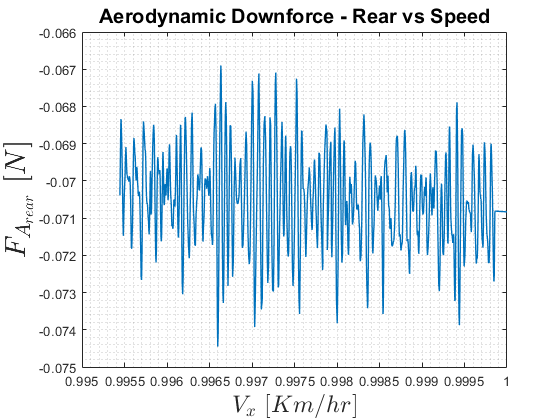


plot(vel_kmph,Faero_down_2,'LineWidth',1);
title("Aerodynamic Downforce - Rear vs Speed",'FontSize',15);
ylabel({'$F_{A_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

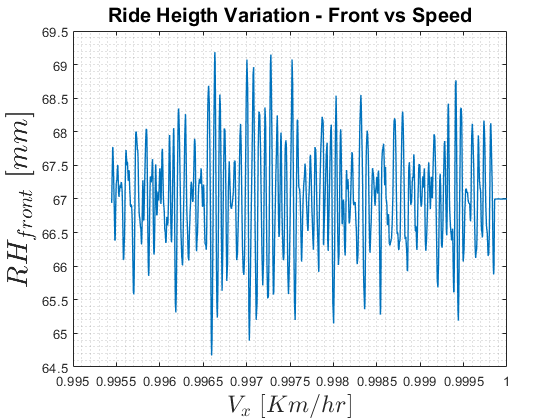


plot(vel_kmph, frh*1000,'LineWidth',1);
title("Ride Heigth Variation - Front vs Speed","FontSize",15);
ylabel({'$RH_{front}\ [mm]$'},'Interpreter','latex','FontSize',22)
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

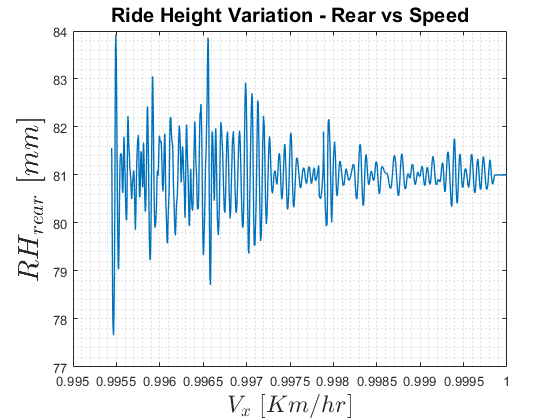


plot(vel_kmph, rrh*1000,'LineWidth',1);
title("Ride Height Variation - Rear vs Speed","FontSize",15);
ylabel({'$RH_{rear}\ [mm]$'},'Interpreter','latex','FontSize',22)
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

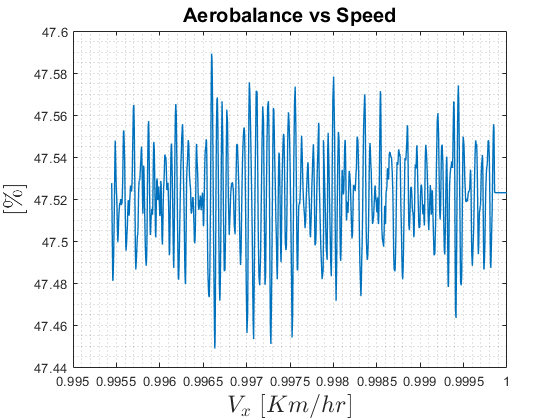


plot(vel_kmph, aeroBalance,'LineWidth',1);
title("Aerobalance vs Speed","FontSize",15);
ylabel({'$[\%]$'},'Interpreter','latex','FontSize',18)
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

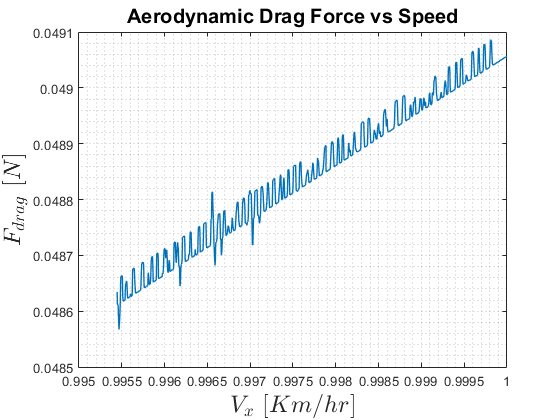


plot(vel_kmph, Faero_drag,'LineWidth',1);
title("Aerodynamic Drag Force vs Speed","FontSize",15);
ylabel({'$F_{drag}\ [N]$'},'Interpreter','latex','FontSize',18)
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;

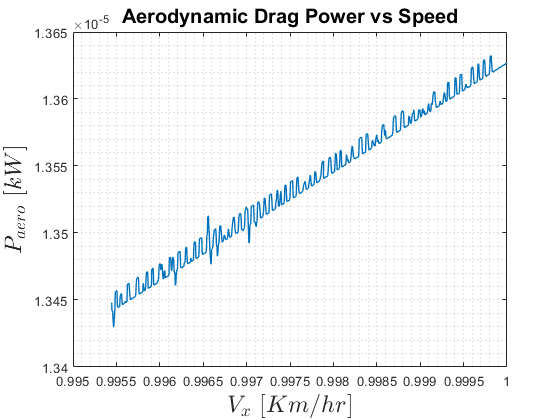


plot(vel_kmph, Paero_drag/1000,'LineWidth',1);
title("Aerodynamic Drag Power vs Speed","FontSize",15);
ylabel({'$P_{aero}\ [kW]$'},'Interpreter','latex','FontSize',18)
xlabel({'$V_x\ [Km/hr]$'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Basic Outputs

In the context of this model, basic outputs are defined as the degrees of freedom which are obtained directly as a result of the numerical integration of the model. 

### Deflections

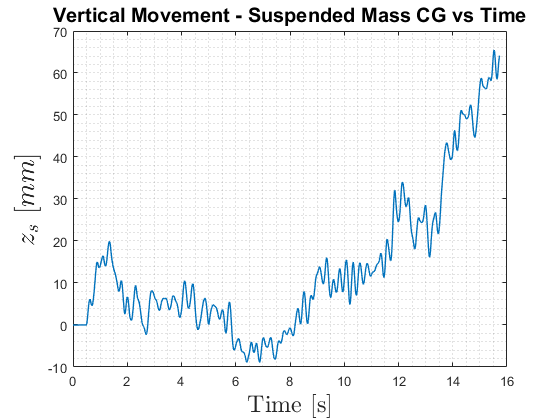

% Display
plot(time,(o.zs-r.init(1))*1000,'LineWidth',1);
title("Vertical Movement - Suspended Mass CG vs Time",'FontSize',15);
ylabel({'$z_s\ [mm]$'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

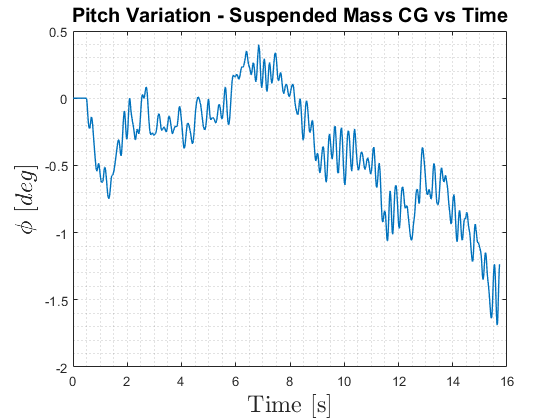


plot(time,rad2deg((o.phi-r.init(2))),'LineWidth',1);
title("Pitch Variation - Suspended Mass CG vs Time",'FontSize',15);
ylabel({'$\phi\ [deg]$'},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

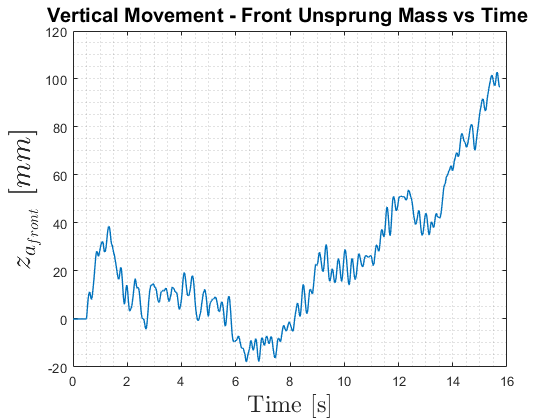


plot(time,(o.za1-r.init(3))*1000,'LineWidth',1);
title("Vertical Movement - Front Unsprung Mass vs Time ",'FontSize',15);
ylabel({'$z_{a_{front}}\ [mm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

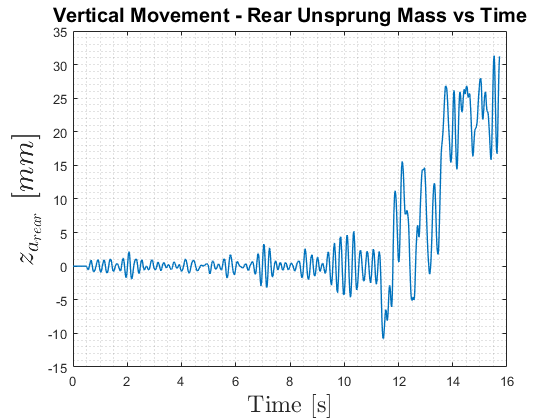


plot(time,(o.za2-r.init(4))*1000,'LineWidth',1);
title("Vertical Movement - Rear Unsprung Mass vs Time",'FontSize',15);
ylabel({'$z_{a_{rear}}\ [mm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Velocities

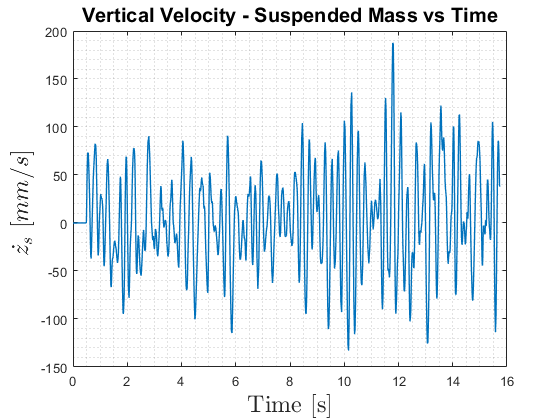

% Display
plot(time,o.zs_d*1000,'LineWidth',1);
title("Vertical Velocity - Suspended Mass vs Time",'FontSize',15);
ylabel({'$\dot{z_s}\ [mm/s]$ '},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

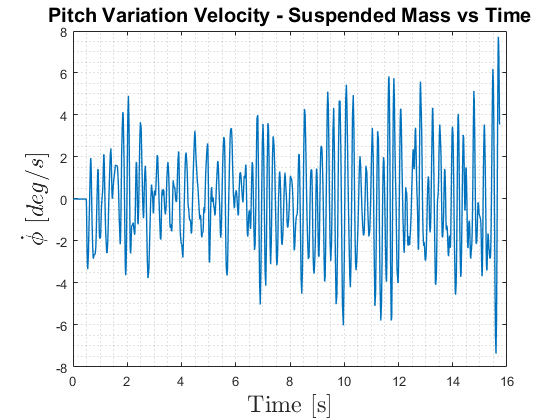


plot(time,rad2deg(o.phi_d),'LineWidth',1);
title("Pitch Variation Velocity - Suspended Mass vs Time",'FontSize',15);
ylabel({'$\dot{\phi}\ [deg/s]$'},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

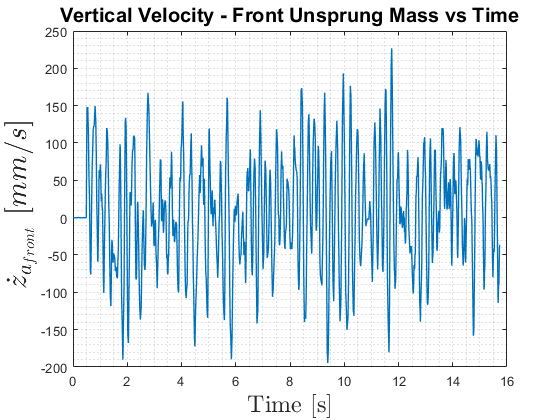


plot(time,o.za1_d*1000,'LineWidth',1);
title("Vertical Velocity - Front Unsprung Mass vs Time",'FontSize',15);
ylabel({'$\dot{z}_{a_{front}}\ [mm/s]$ '},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

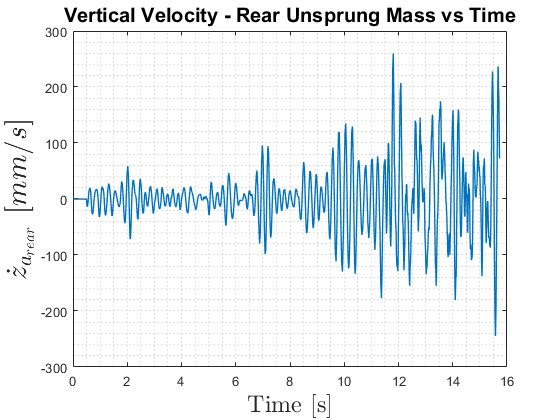


plot(time,o.za2_d*1000,'LineWidth',1);
title("Vertical Velocity - Rear Unsprung Mass vs Time",'FontSize',15);
ylabel({'$\dot{z}_{a_{rear}}\ [mm/s]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Accelerations

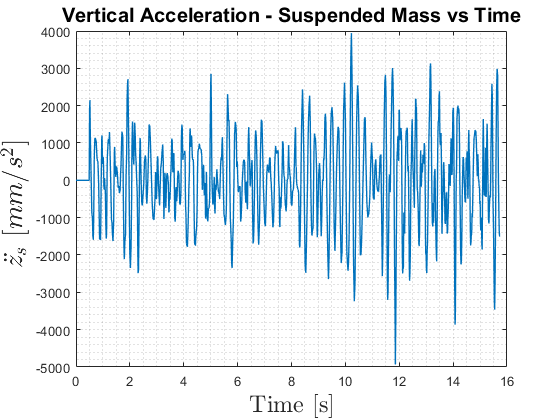

% Computing the accelerations of the 4 dofs

% Sprung Mass Acceleration
zs_dd = [0 ; diff(o.zs_d)./diff(time)];

% Sprung Mass Pitch Acceleration
phi_dd = [0 ; diff(o.phi_d)./diff(time)];

% Unsprung Mass-1 Acceleration
za1_dd = [0 ; diff(o.za1_d)./diff(time)];

% Unsprung Mass-2 Acceleration
za2_dd = [0 ; diff(o.za2_d)./diff(time)];

% Display
plot(time,zs_dd*1000,'LineWidth',1);
title("Vertical Acceleration - Suspended Mass vs Time",'FontSize',15);
ylabel({'$\ddot{z_s}\ [mm/s^2]$ '},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

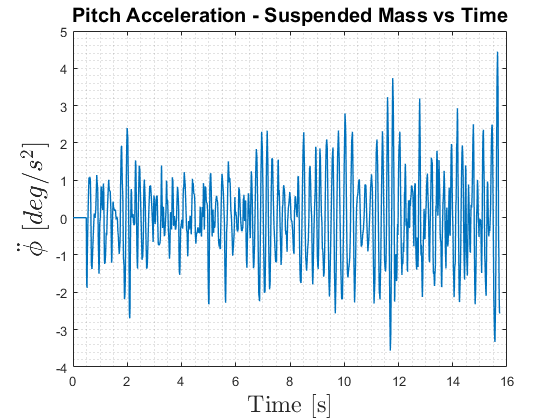


plot(time,phi_dd,'LineWidth',1);
title("Pitch Acceleration - Suspended Mass vs Time",'FontSize',15);
ylabel({'$\ddot{\phi}\ [deg/s^2]$'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

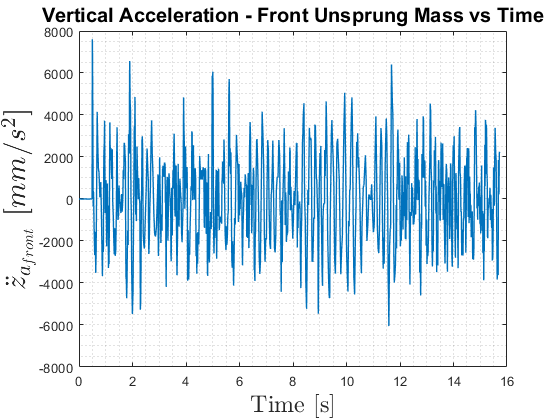


plot(time,za1_dd*1000,'LineWidth',1);
title("Vertical Acceleration - Front Unsprung Mass vs Time",'FontSize',15);
ylabel({'$\ddot{z}_{a_{front}}\ [mm/s^2]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

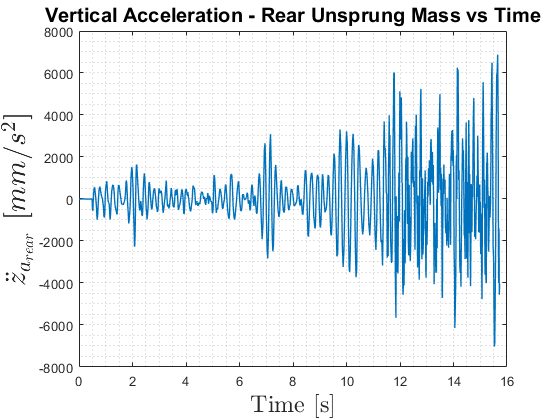


plot(time,za2_dd*1000,'LineWidth',1);
title("Vertical Acceleration - Rear Unsprung Mass vs Time",'FontSize',15);
ylabel({'$\ddot{z}_{a_{rear}}\ [mm/s^2]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Vehicle Outputs

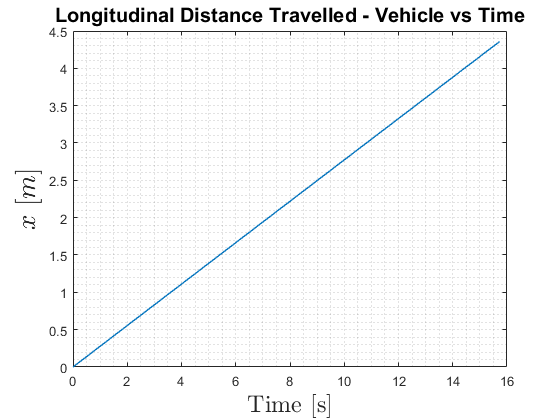

% Extracting Vehicle Level Outputs

% Vehicle Acceleration
Ax = [0 ; diff(o.Vx)./diff(time)];

% Display

plot(time,o.x,"LineWidth",1);
title("Longitudinal Distance Travelled - Vehicle vs Time",'FontSize',15);
ylabel({'$x\ [m]$'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

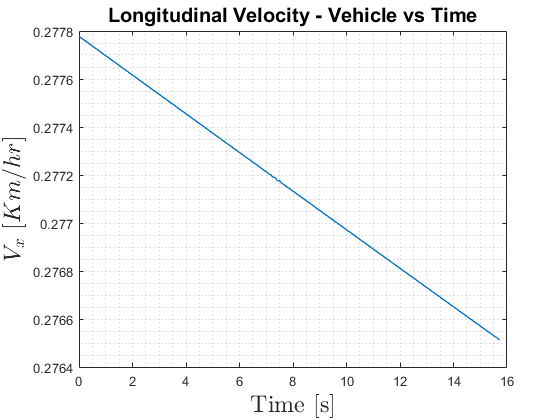


plot(time,o.Vx,"LineWidth",1);
title("Longitudinal Velocity - Vehicle vs Time",'FontSize',15);
ylabel({'$V_x\ [Km/hr] $'},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

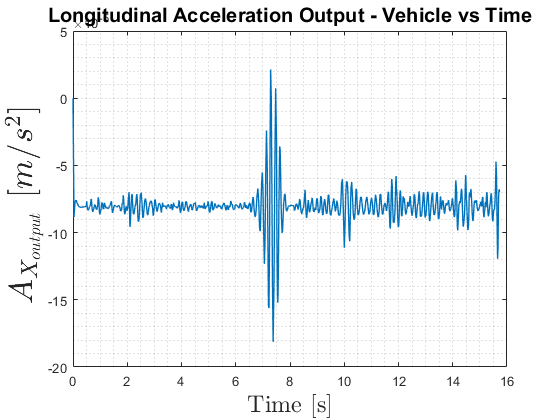


plot(time,Ax,'LineWidth',1);
title("Longitudinal Acceleration Output - Vehicle vs Time",'FontSize',15);
ylabel({'$A_{X_{output}}\ [m/s^2]$ '},'Interpreter','latex','FontSize',25);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Front Wheel Outputs

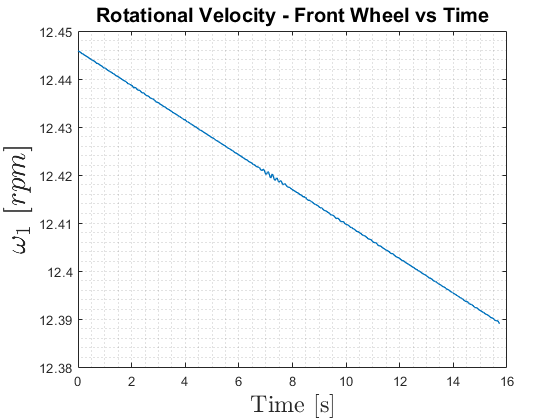

% Extracting the outputs of the Front Wheel

sr1T = -(o.Vx - r.rE1.*o.omega1)./o.Vx;
% Display

plot(time,o.omega1*(60/(2*pi)),"LineWidth",1);
title("Rotational Velocity - Front Wheel vs Time",'FontSize',15);
ylabel({'$\omega_1\ [rpm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

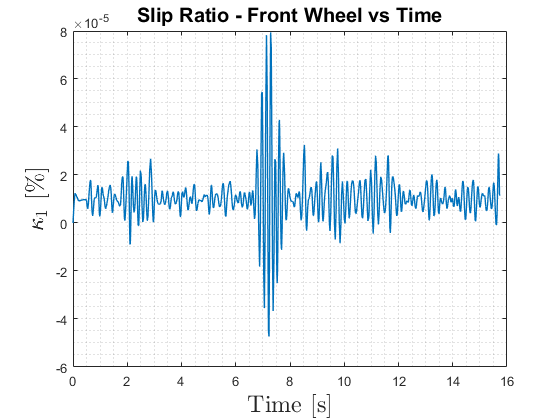


plot(time,o.sr1*100,"LineWidth",1);
title("Slip Ratio - Front Wheel vs Time",'FontSize',15);
ylabel({'$\kappa_1\ [\%]$'},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Rear Wheel Outputs

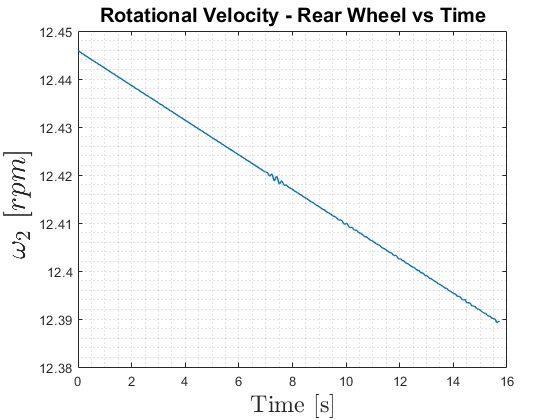

% Extracting the outputs of the Rear Wheel


sr2T = -(o.Vx - r.rE2.*o.omega2)./o.Vx;

% Display

plot(time,o.omega2*(60/(2*pi)),"LineWidth",1);
title("Rotational Velocity - Rear Wheel vs Time",'FontSize',15);
ylabel({'$\omega_2\ [rpm]$ '},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

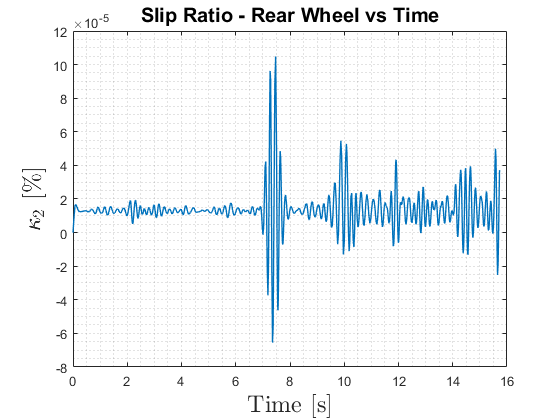


plot(time,o.sr2*100,"LineWidth",1);
title("Slip Ratio - Rear Wheel vs Time",'FontSize',15);
ylabel({'$\kappa_2\ [\%]$'},'Interpreter','latex','FontSize',18);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Advanced Outputs

In the context of this model, advanced outputs are the outputs which require computation and/or post processing using the basic degrees of freedom

### Deflections

- Front and Rear Suspension Deflection

- Front and Rear Tire Deflection

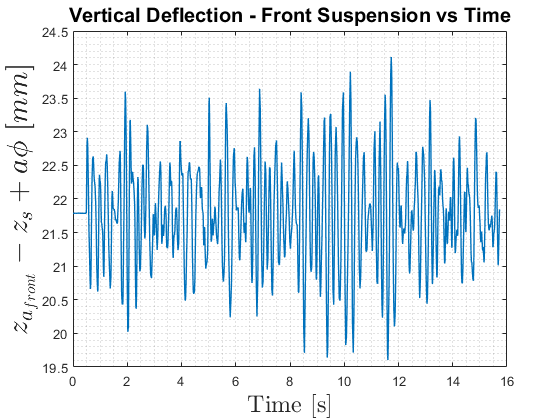

% Computing the Deflections

% Spring Deflection - Front and Rear
defSus1 = o.za1 - o.zs + hcar.dis_a12cg*o.phi;
defSus2 = o.za2 - o.zs - hcar.dis_a22cg*o.phi;

% Tire Deflection - Front and Rear
defT1 = zr1 - (o.za1);
defT2 = zr2 - (o.za2);

% Display
plot(time, defSus1*1000,'LineWidth',1);
title("Vertical Deflection - Front Suspension vs Time","FontSize",15);
ylabel({'$z_{a_{front}} - z_s + a\phi\ [mm]$'},'Interpreter','latex','FontSize',22)
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

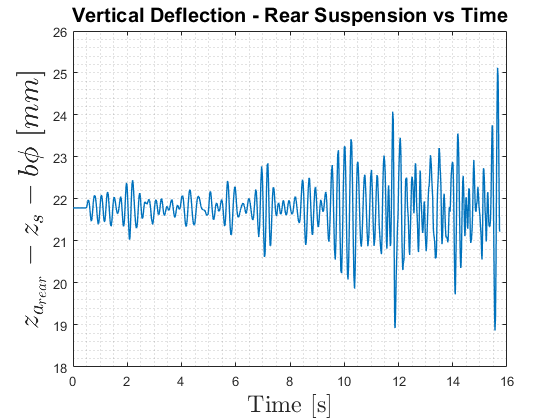


plot(time, defSus2*1000,'LineWidth',1);
title("Vertical Deflection - Rear Suspension vs Time","FontSize",15);
ylabel({'$z_{a_{rear}} - z_s - b\phi\ [mm]$'},'Interpreter','latex','FontSize',22)
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

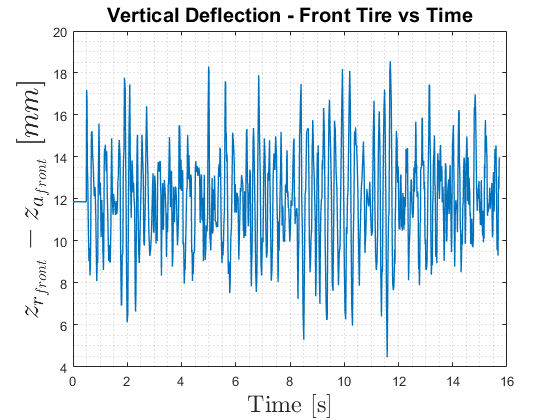


plot(time, defT1*1000,'LineWidth',1);
title("Vertical Deflection - Front Tire vs Time","FontSize",15);
ylabel({'$z_{r_{front}} - z_{a_{front}}\ [mm]$'},'Interpreter','latex','FontSize',22)
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

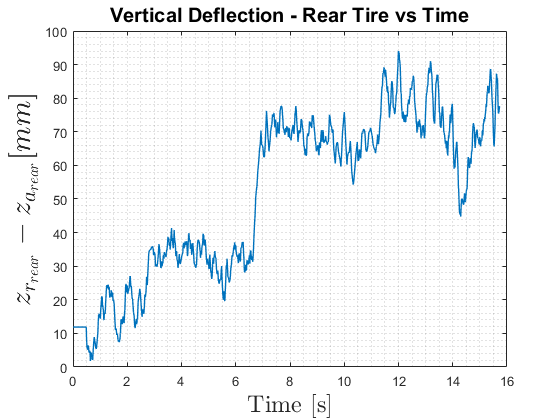


plot(time, defT2*1000,'LineWidth',1);
title("Vertical Deflection - Rear Tire vs Time","FontSize",15);
ylabel({'$z_{r_{rear}} - z_{a_{rear}} [mm]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


### Velocities

- Front and Rear Suspension Velocities

- Front and Rear Tire Deflection Velocities

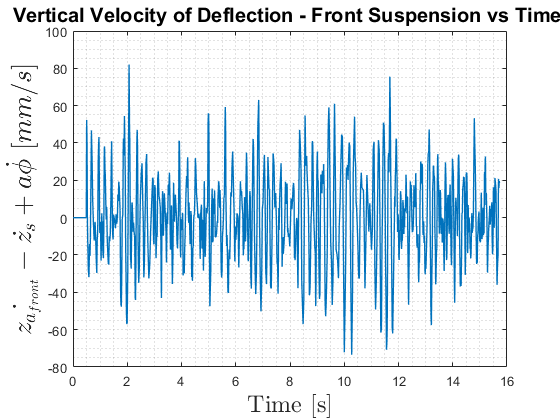

% Computing the Velocities

% Suspension Velocity - Front and Rear
velSus1 = o.za1_d - o.zs_d + hcar.dis_a12cg*o.phi_d;
velSus2 = o.za2_d - o.zs_d - hcar.dis_a22cg*o.phi_d;

% Tire Velocitie - Front and Rear
velT1 = zr1_d - (o.za1_d);
velT2 = zr2_d - (o.za2_d);

% Display
plot(time, velSus1*1000,'LineWidth',1);
title("Vertical Velocity of Deflection - Front Suspension vs Time ","FontSize",15);
ylabel({'$\dot{z_{a_{front}}} - \dot{z_s} + a\dot{\phi}\ [mm/s]$'}, ...
    'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

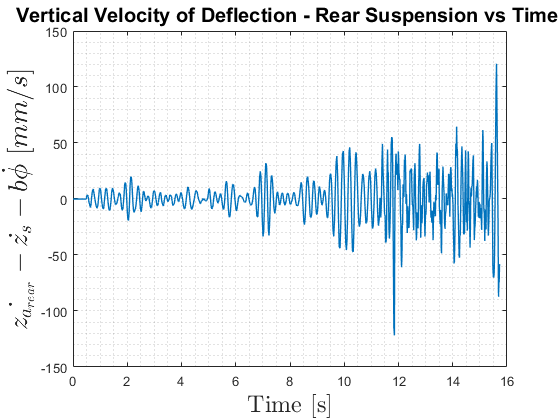


plot(time, velSus2*1000,'LineWidth',1);
title("Vertical Velocity of Deflection - Rear Suspension vs Time ","FontSize",15);
ylabel({'$\dot{z_{a_{rear}}} - \dot{z_s} - b\dot{\phi}\ [mm/s]$'}, ...
    'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

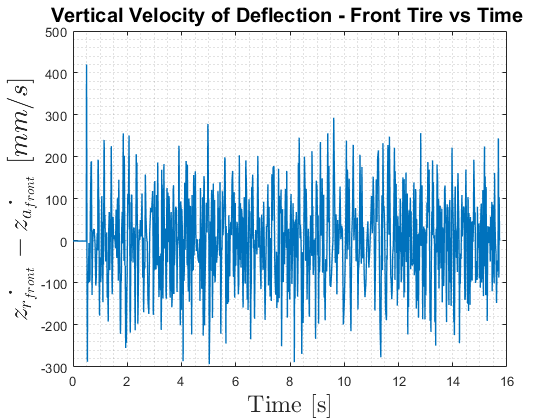


plot(time, velT1*1000,'LineWidth',1);
title("Vertical Velocity of Deflection - Front Tire vs Time ","FontSize",15);
ylabel({'$\dot{z_{r_{front}}} - \dot{z_{a_{front}}}\ [mm/s]$'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

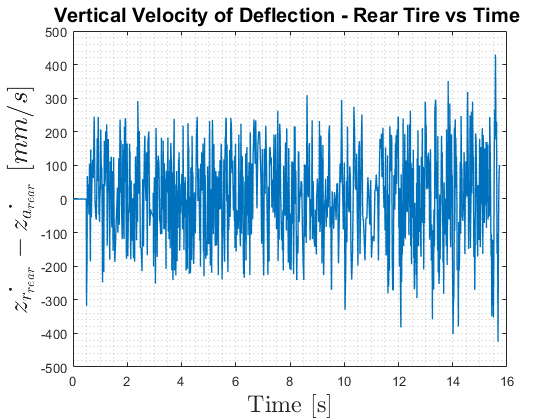


plot(time, velT2*1000,'LineWidth',1);
title("Vertical Velocity of Deflection - Rear Tire vs Time ","FontSize",15);
ylabel({'$\dot{z_{r_{rear}}} - \dot{z_{a_{rear}}}\ [mm/s]$'},'Interpreter','latex','FontSize',20)
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


### Weight Transfers

% % Computing the Weight Transfers
% m = hcar.mass_sm + hcar.mass_usm_1 + hcar.mass_usm_2;
% 
% % Suspended Weight Transfer
% Ws = (m.*Ax*hcar.cg_SM_Height)./(hcar.w2w);
% 
% % Non Suspended Weight Transfer
% mnsm = hcar.mass_usm_1 + hcar.mass_usm_2;
% Wnsm = (mnsm.*Ax*hcar.tire1.unloadedRadius)./(hcar.w2w);
% 
% 
% 
% plot(time,Ws,'LineWidth',1);
% title("Elastic Weight Transfer",'FontSize',15);
% ylabel({'$W_s$ [N]'},'Interpreter','latex','FontSize',16);
% xlabel("Time [s]","FontSize",14);
% grid minor;


### Forces

#### Inertial Forces and Torques

- Inertial Forces of Sprung and Unsprung Masees 

- Inertial Torque of Sprung Mass

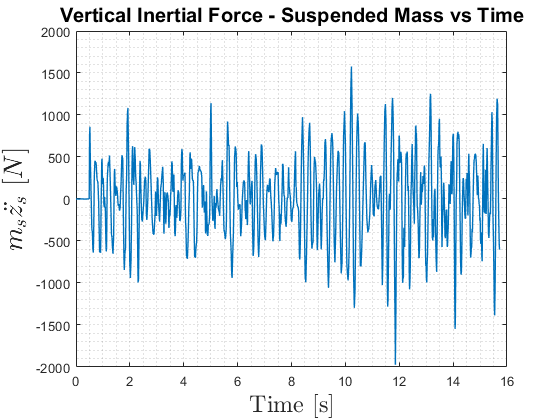

% Computing the Inertial Forces and Torques

% Sprung Mass Inertial Forces and Torques
F_zs = hcar.mass_sm.*zs_dd;
F_phis = hcar.Inertia.*phi_dd;

% Unsprung Mass-1 Inertial Forces
F_za1 = hcar.mass_usm_1.*za1_dd;

% Unsprung Mass-2 Inrtial Forces
F_za2 = hcar.mass_usm_2.*za2_dd;

% Display
plot(time,F_zs,'LineWidth',1);
title("Vertical Inertial Force - Suspended Mass vs Time",'FontSize',15);
ylabel({'$m_s \ddot{z_s}\ [N]$'}, ...
    'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

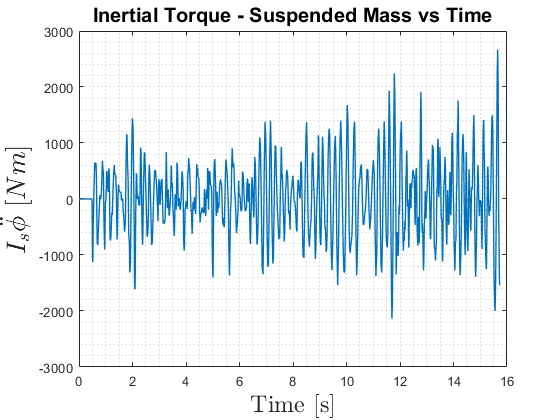


plot(time,F_phis,'LineWidth',1);
title("Inertial Torque - Suspended Mass vs Time",'FontSize',15);
ylabel({'$I_s \ddot{\phi}\ [Nm]$'}, ...
    'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

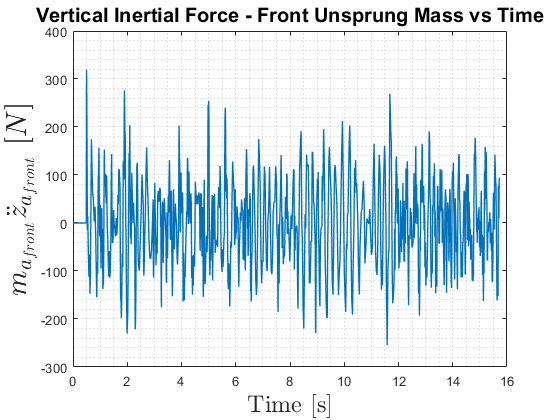


plot(time,F_za1,'LineWidth',1);
title("Vertical Inertial Force - Front Unsprung Mass vs Time",'FontSize',15);
ylabel({'$m_{a_{front}} \ddot{z}_{a_{front}}\ [N]$'}, ...
    'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

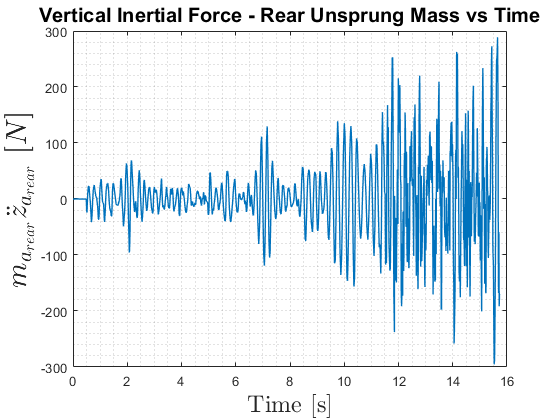


plot(time,F_za2,'LineWidth',1);
title("Vertical Inertial Force - Rear Unsprung Mass vs Time",'FontSize',15);
ylabel({'$m_{a_{rear}} \ddot{z}_{a_{rear}}\ [N]$'}, ...
    'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


#### Component Forces

- Front and Rear Spring Force

- Front and Rear Bumpstop Force

- Front and Rear Elastic Force (Spring + Bumpstop)

- Front and Rear Damping Force

- Front and Rear Tire Spring Force

- Front and Rear Tire Damping Force

- **Front and Rear Tire Longitudinal Force**

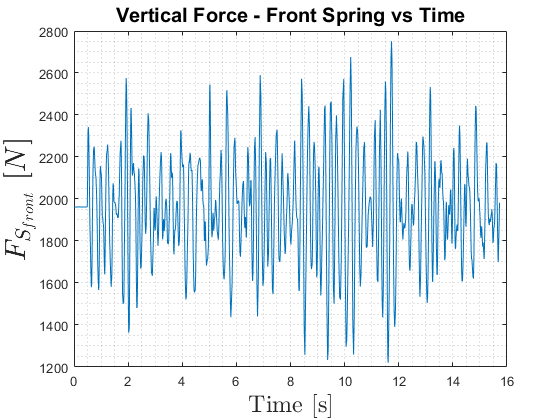

% Computing the Spring Force - Front and Rear
fs1 = hcar.coil1.spring.Get_Force(defSus1,0);
fs2 = hcar.coil2.spring.Get_Force(defSus2,0);

% Computing the Bumpstop Force - Front and Rear
fb1 = hcar.coil1.bumpStop.Get_Force(defSus1,0);
fb2 = hcar.coil2.bumpStop.Get_Force(defSus2,0);

% Computing the Elastic Force - Front and Rear
fe1 = hcar.coil1.Get_Force(defSus1,0);
fe2 = hcar.coil2.Get_Force(defSus2,0);

% Computing the Damping Force
fd1 = hcar.damper1.Get_Force(velSus1);
fd2 = hcar.damper2.Get_Force(velSus2);

% Computing the Tire Spring Force
fkt1 = hcar.tire1.kt.*defT1;
fkt2 = hcar.tire2.kt.*defT2;

% Computing the Tire Damping Force
fdt1 = hcar.tire1.dt.*velT1;
fdt2 = hcar.tire2.dt.*velT2;

% Computing Tire Longitudinal Force
fxy_1 = MF5ss_eval(fkt1 + fdt2,o.sr1,0,0,hcar.tire1.mf);
fxy_2 = MF5ss_eval(fkt2 + fdt2,o.sr2,0,0,hcar.tire2.mf);

% Display
plot(time,fs1);
title("Vertical Force - Front Spring vs Time",'FontSize',15);
ylabel({'$F_{S_{front}}\ [N] $'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

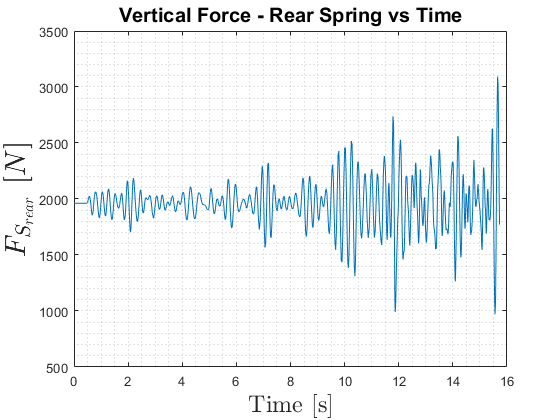


plot(time,fs2);
title("Vertical Force - Rear Spring vs Time",'FontSize',15);
ylabel({'$F_{S_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

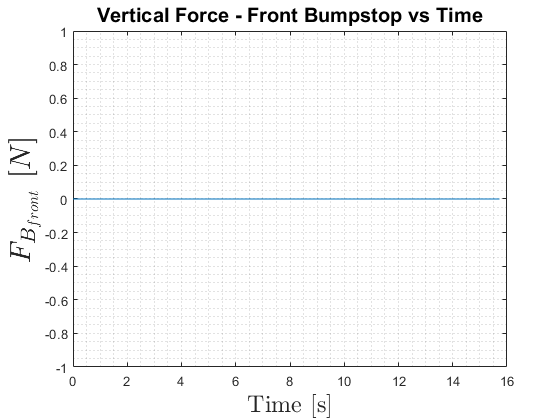


plot(time,fb1);
title("Vertical Force - Front Bumpstop vs Time",'FontSize',15);
ylabel({'$F_{B_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

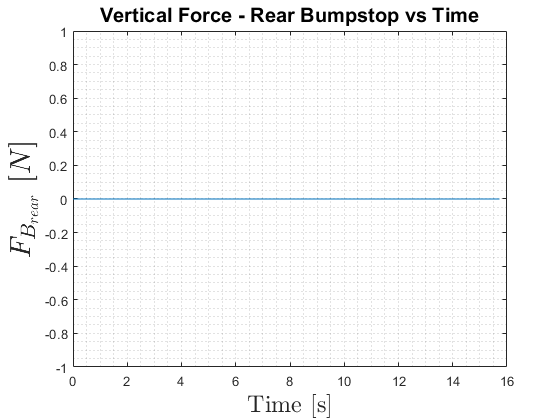


plot(time,fb2);
title("Vertical Force - Rear Bumpstop vs Time",'FontSize',15);
ylabel({'$F_{B_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

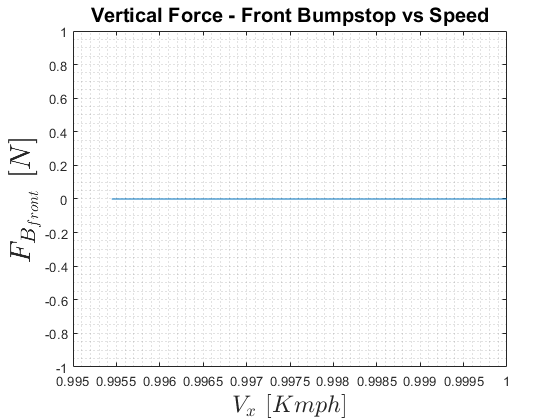



plot(vel_kmph,fb1);
title("Vertical Force - Front Bumpstop vs Speed",'FontSize',15);
ylabel({'$F_{B_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Kmph]$'},'Interpreter','latex','FontSize',18);
grid minor;

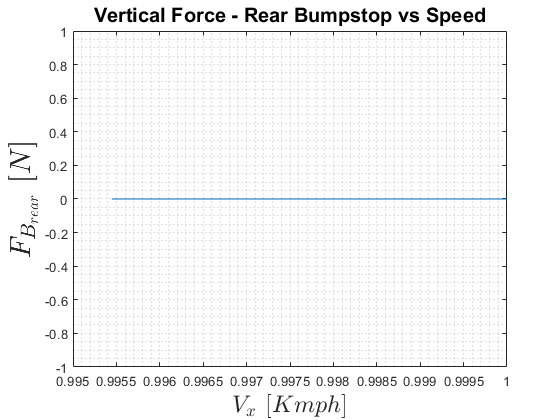


plot(vel_kmph,fb2);
title("Vertical Force - Rear Bumpstop vs Speed",'FontSize',15);
ylabel({'$F_{B_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Kmph]$'},'Interpreter','latex','FontSize',18);
grid minor;

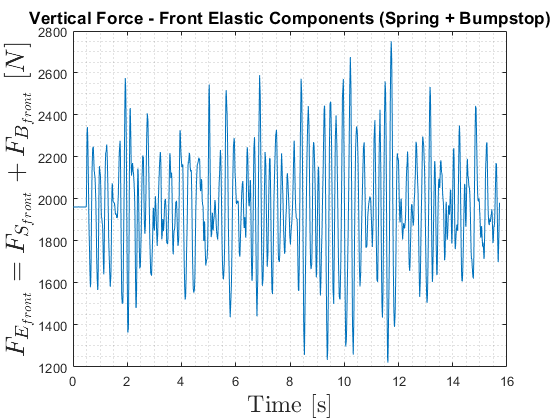


plot(time,fe1);
title("Vertical Force - Front Elastic Components (Spring + Bumpstop)",'FontSize',13);
ylabel({'$F_{E_{front}} = F_{S_{front}} + F_{B_{front}}\ [N]$'}, ...
    'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

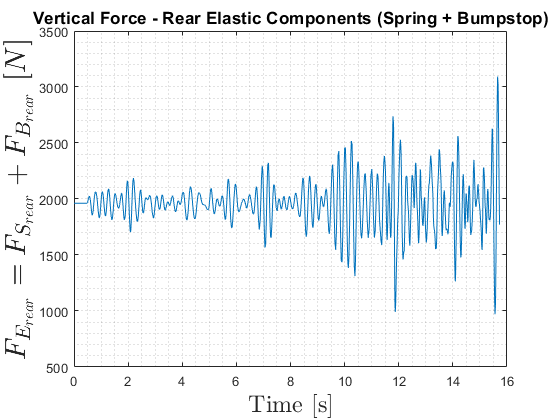


plot(time,fe2);
title("Vertical Force - Rear Elastic Components (Spring + Bumpstop)",'FontSize',13);
ylabel({'$F_{E_{rear}} = F_{S_{rear}} + F_{B_{rear}}\ [N]$'}, ...
    'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

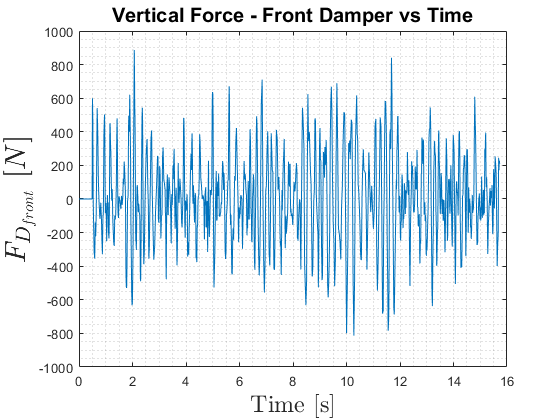


plot(time,fd1);
title("Vertical Force - Front Damper vs Time",'FontSize',15);
ylabel({'$F_{D_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

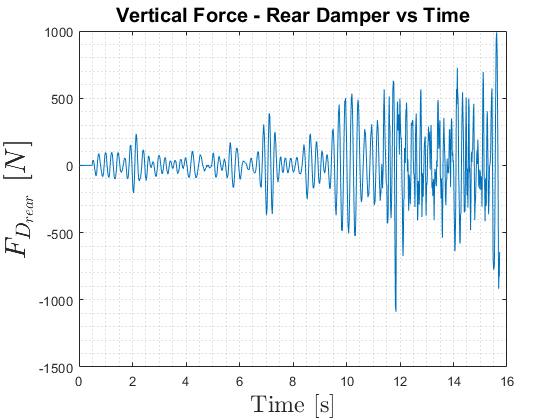


plot(time,fd2);
title("Vertical Force - Rear Damper vs Time",'FontSize',15);
ylabel({'$F_{D_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

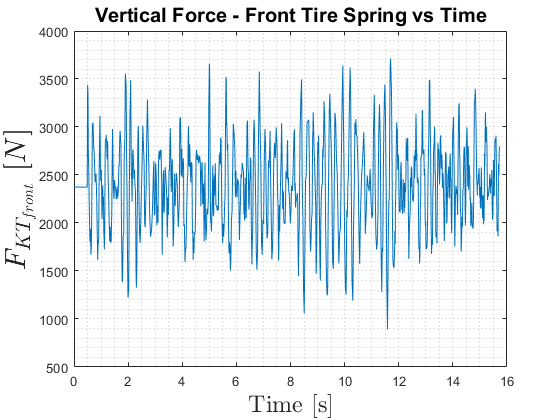


plot(time,fkt1);
title("Vertical Force - Front Tire Spring vs Time",'FontSize',15);
ylabel({'$F_{KT_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

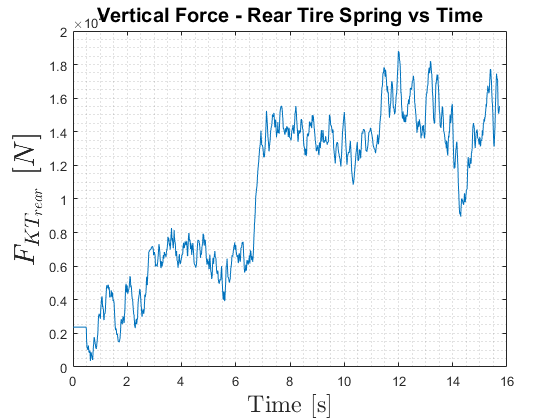


plot(time,fkt2);
title("Vertical Force - Rear Tire Spring vs Time",'FontSize',15);
ylabel({'$F_{KT_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

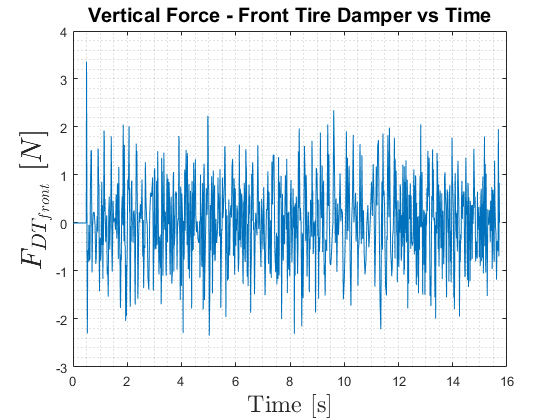


plot(time,fdt1);
title("Vertical Force - Front Tire Damper vs Time",'FontSize',15);
ylabel({'$F_{DT_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

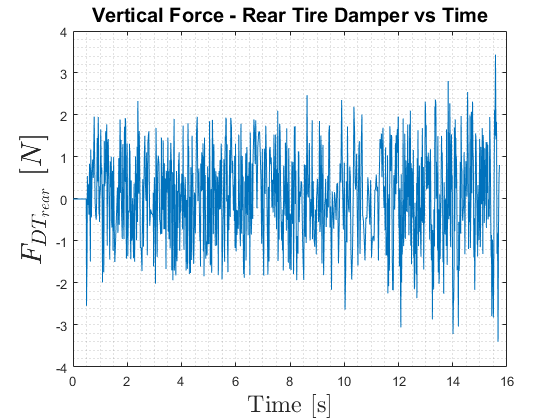


plot(time,fdt2);
title("Vertical Force - Rear Tire Damper vs Time",'FontSize',15);
ylabel({'$F_{DT_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

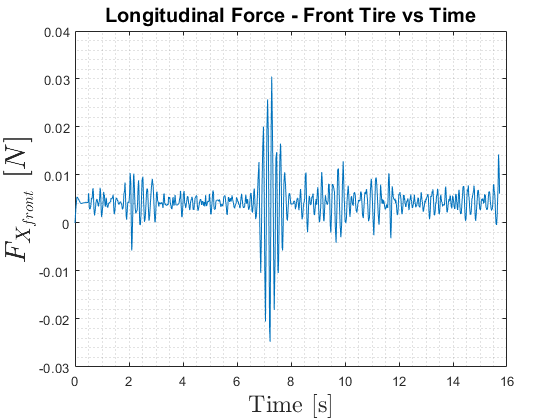


plot(time,fxy_1);
title("Longitudinal Force - Front Tire vs Time",'FontSize',15);
ylabel({'$F_{X_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

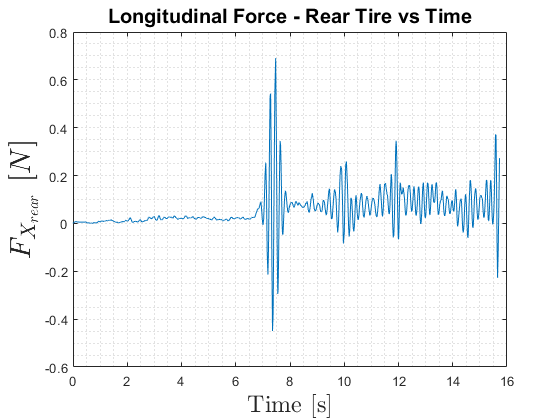


plot(time,fxy_2);
title("Longitudinal Force - Rear Tire vs Time",'FontSize',15);
ylabel({'$F_{X_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


### AUX - IC Arm Angle

The variation of the angle of the IC arm is a pre-requisite for computing the jacking force and hence it is computed here.

However, to maintain the integrity of the strcuture of the report, this is displayed in the next section

% Computing the IC Arm Angle 

% Front
hyp1 = hcar.axleSusp.hyp_1;
th1 = -hyp1.*(o.za1 - o.za1(1)); % Variation about static angle 
% (hence calibrated). REMEMBER +deflection is -angle
thComb1 = hcar.axleSusp.th_1 + 0*th1; % Combined with static anti

% Rear
hyp2 = hcar.axleSusp.hyp_2;
th2 = hyp2.*(o.za2 - o.za2(1)); % Variation about static angle 
% (hence calibrated). REMEMBER +deflection is +angle
thComb2 = hcar.axleSusp.th_2 + 0*th2; % Combined with static anti

### Jacking Forces

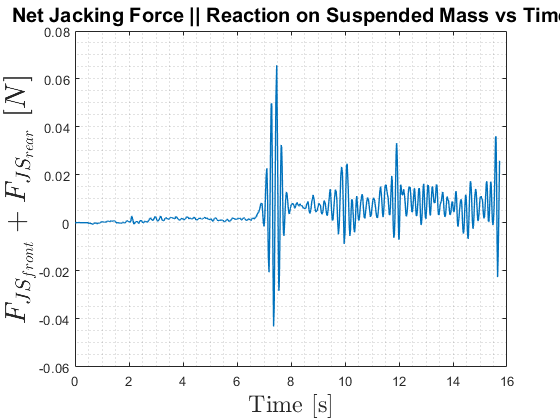

% Computing the Jacking Forces

% Front
fx1 = fxy_1 - hcar.mass_usm_1*Ax;
Fz1 = -fx1.*tan(thComb1);

% Rear
fx2 = fxy_2 - hcar.mass_usm_2*Ax;
Fz2 = fx2.*tan(thComb2);

% Display
plot(time,Fz1+Fz2,'LineWidth',1);
title("Net Jacking Force || Reaction on Suspended Mass vs Time", ...
    'FontSize',15);
ylabel({'$F_{JS_{front}} + F_{JS_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

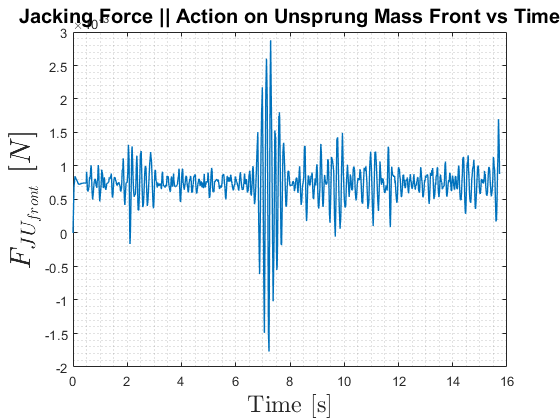


plot(time,-Fz1,'LineWidth',1);
title("Jacking Force || Action on Unsprung Mass Front vs Time", ...
    'FontSize',15);
ylabel({'$F_{JU_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

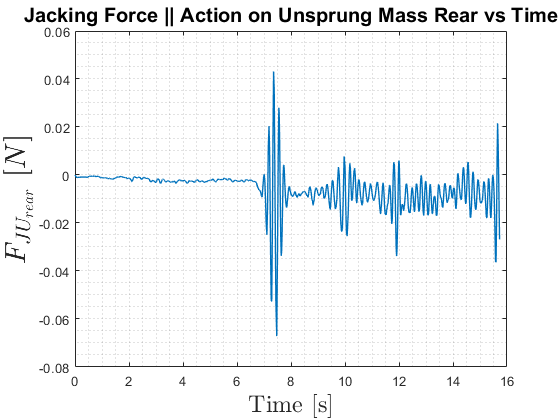


plot(time,-Fz2,'LineWidth',1);
title("Jacking Force || Action on Unsprung Mass Rear vs Time", ...
    'FontSize',15);
ylabel({'$F_{JU_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

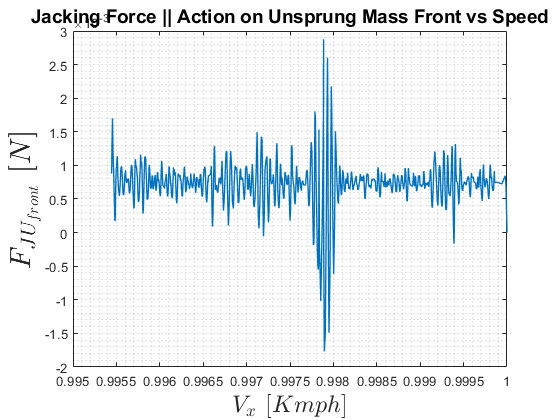


plot(vel_kmph,-Fz1,'LineWidth',1);
title("Jacking Force || Action on Unsprung Mass Front vs Speed", ...
    'FontSize',14);
ylabel({'$F_{JU_{front}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Kmph]$'},'Interpreter','latex','FontSize',18);
grid minor;

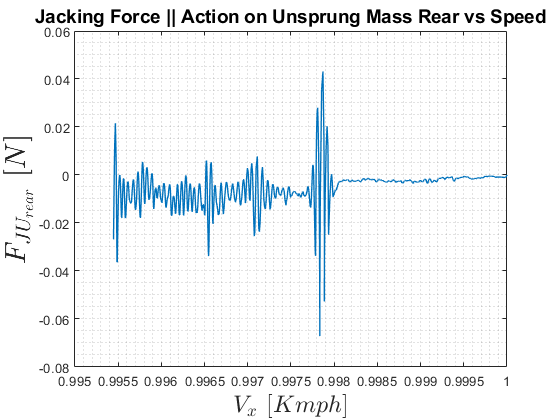


plot(vel_kmph,-Fz2,'LineWidth',1);
title("Jacking Force || Action on Unsprung Mass Rear vs Speed", ...
    'FontSize',14);
ylabel({'$F_{JU_{rear}}\ [N]$'},'Interpreter','latex','FontSize',22);
xlabel({'$V_x\ [Kmph]$'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Geometry

### IC Arm Angle

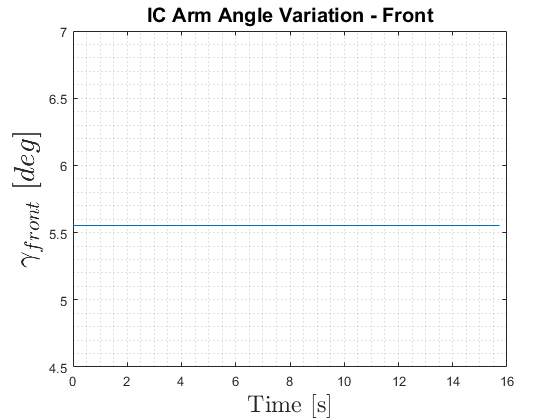

% Display

plot(time,rad2deg(thComb1));
title("IC Arm Angle Variation - Front","FontSize",15);
ylabel({'$\gamma_{front}\ [deg]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

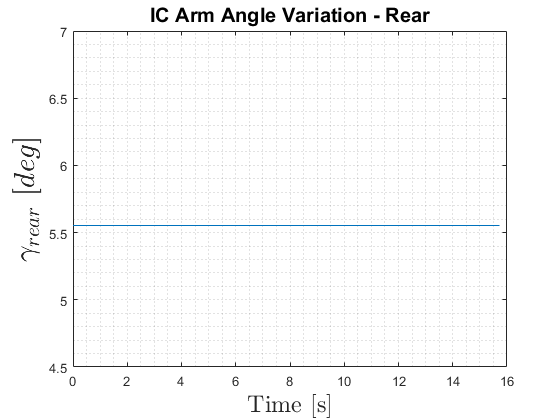


plot(time,rad2deg(thComb2));
title("IC Arm Angle Variation - Rear","FontSize",15);
ylabel({'$\gamma_{rear}\ [deg]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


### Resultant Force Angle

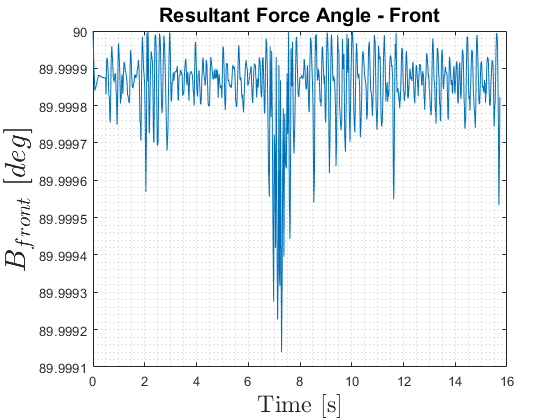

% Computing the Resultant Force Angle

% Front Resultant Force Angle
FeFg1 = -fs1 + Fz1;
B1 = atan(abs(FeFg1)./abs(fxy_1));

% Rear Resultant Force Angle
FeFg2 = fs2 + Fz2;
B2 = atan(abs(FeFg2)./abs(fxy_2));

% Display

plot(time,rad2deg(B1));
title("Resultant Force Angle - Front","FontSize",15);
ylabel({'$B_{front}\ [deg]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

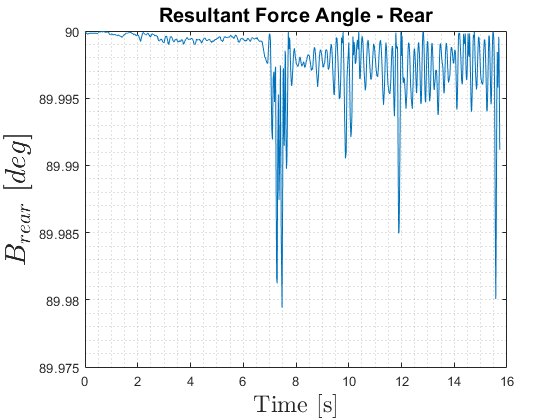


plot(time,rad2deg(B2));
title("Resultant Force Angle - Rear","FontSize",15);
ylabel({'$B_{rear}\ [deg]$'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Anti Features

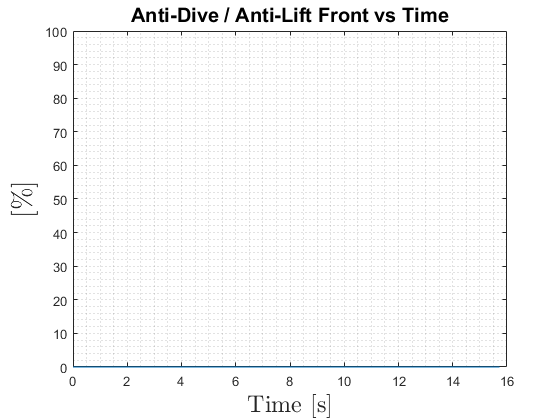

% Computing the Anti-Features

% Front Anti-Dive / Anti-Lift
anti1 = 100*tan(thComb1)./tan(B1);

% Rear Anti-Lift / Anti-Squat
anti2 = 100*tan(thComb2)./tan(B2);

% Display
plot(time,anti1);
title("Anti-Dive / Anti-Lift Front vs Time","FontSize",15);
ylabel({'$[\%]$'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
ylim([0 100]);
grid minor;

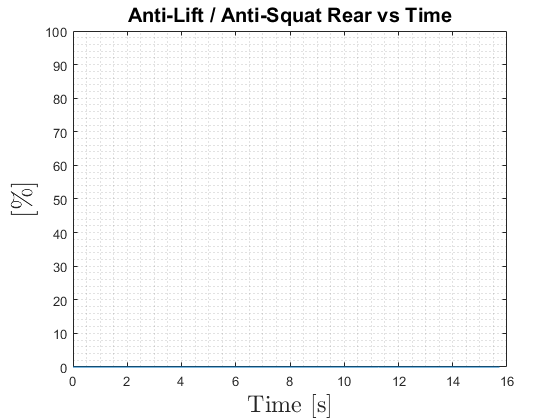


plot(time,anti2);
title("Anti-Lift / Anti-Squat Rear vs Time","FontSize",15);
ylabel({'$ [\%] $'},'Interpreter','latex','FontSize',20);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
ylim([0 100]);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------


## Radii

### Tire Loaded Radius

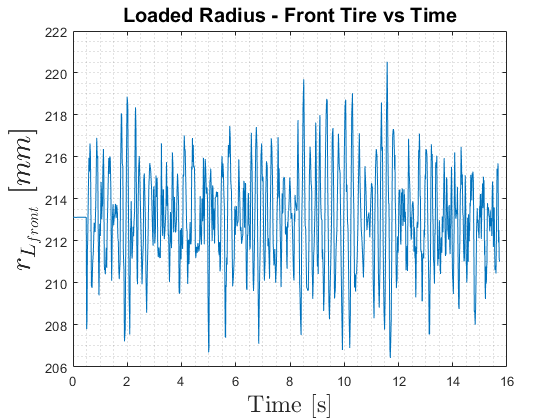

% Computing the Tire Loaded Radius

rL1 = hcar.tire1.unloadedRadius - defT1;

rL2 = hcar.tire2.unloadedRadius - defT2;

% Display

plot(time,rL1*1000);
title("Loaded Radius - Front Tire vs Time","FontSize",15);
ylabel({'$ r_{L_{front}}\ [mm] $'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

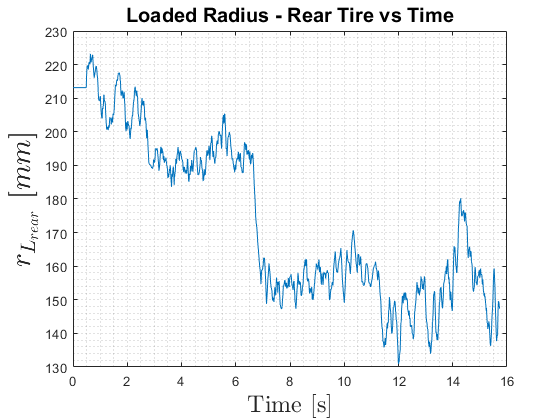


plot(time,rL2*1000);
title("Loaded Radius - Rear Tire vs Time","FontSize",15);
ylabel({'$ r_{L_{rear}}\ [mm] $'},'Interpreter','latex','FontSize',22);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;


disp("--------------------------------------------------------------------------------------------");

--------------------------------------------------------------------------------------------
